# **Analytic Performance Estimator**

**Summary:**

This program summarizes most of my work on the small KID's project. In here the most of the quasi analytical model that i use to predict/estimate performance of cetain set of parameters. 

## Physical constants:

%-Useful Physics constants
phyconst.c = 299792458 ;% [m/s] - Speed of light! 
phyconst.epsilon0 = 8.854187E-12;% [C/m]
phyconst.mu0 = 1/(phyconst.epsilon0*(phyconst.c^2)) % [s/(C*m) = Henry/m]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.8542e-12
         mu0: 1.2566e-06


phyconst.h = 6.626E-34 % [J*s]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.8542e-12
         mu0: 1.2566e-06
           h: 6.6260e-34


phyconst.kb = 1.38E-23 % [J/K]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.8542e-12
         mu0: 1.2566e-06
           h: 6.6260e-34
          kb: 1.3800e-23


phyconst.e  = 1.602E-19 % [Coulomb]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.8542e-12
         mu0: 1.2566e-06
           h: 6.6260e-34
          kb: 1.3800e-23
           e: 1.6020e-19


## Setup

%% Setup
%clc
close all 
%clear
tic
%clear all %clear classes % Increasingly strong statements about clearing
%everything
% Parameters
Z0 = 79.605;%[Ohm] --> value from CPW simulation sonnet. varies only slightly as function of freq <0.1%
Z0_PEC =65.3696 ;%%[Ohm] --> value from CPW simulation sonnet. varies only slightly as function of freq <3ppm
epsilon_eff = 10.6008;%[-] --> value from CPW simulation sonnet. varies only slightly as function of freq <0.1%
epsilon_eff_PEC = 7.1484;%[-] --> value from CPW simulation sonnet. varies only slightly as function of freq <0.1%
epsilon0 = 8.854187E-12;% [C/m]
length_M = 0.001;%[m]
d = 295E-9;%[m]

%Data path
addpath('.\Sonnet_data')
filename_begin = 'PPCV0_9_9A';
filename_end = '.csv';
filename_CPW_SC = 'AlHybridV0_0_3_SC.csv';
filename_CPW_PEC = 'AlHybridV0_0_3_PEC.csv';
%Extended with (1-1-1) and (0.5-0.5-0.5) CPW.
filename_CPW_SC1 = 'AlHybridV0_0_3_SC1.csv';
filename_CPW_PEC1 = 'AlHybridV0_0_3_PEC1.csv';
filename_CPW_SC0_5 = 'AlHybridV0_0_3_SC0_5.csv';
filename_CPW_PEC0_5 = 'AlHybridV0_0_3_PEC0_5.csv';



## Loading data and making objects

Over here the data is being added to the program.  Objects for the PPC and the CPW are made. Also objects are made that represent the theoretical model of the PPC and the CPW.

%% Loading Data and making objects.
A_filename_umsquared = [12710,10056,8320,7094,6184,5480,4920,4464,4086,3766,3493,3257,3051,2869,2708,2564,2434,2317,2211,2114];
%New data which has not been tested yet: A_filename_umsquared = [12769,10000, 8281 ,7056, 6241, 5476, 4900, 4489, 4096, 3721, 3481, 3249, 3025, 2916, 2704, 2601, 2401, 2304, 2209, 2116];
A_ppc = A_filename_umsquared.*((1E-6)^2);

%5Target Toy model data validation
F0_5Target = [5.86083 5.5316 5.33138 4.72955 4.01304 3.10839].*10^9;% Old data
PPC_To_be_squared = [47.0213 50 52.0384 59.1016 70.1727 91.214].*10^(-6);% Old data
A_ppc_5Target = PPC_To_be_squared.*PPC_To_be_squared;

F0_5TargetV2 = [3.9788 5.2523 5.44361 5.7568 8.64393].*10^9;% New data
PPC_To_be_squaredV2 = [70 52 50 47 29].*10^(-6);% New data
A_ppc_5TargetV2 = PPC_To_be_squaredV2.*PPC_To_be_squaredV2;

% Jochem Code data
F0_Jochem = [2310621857.66901,2594151197.17164,2848091619.57189,3080193995.21574,3294570175.75902,3495048293.57827,3683595761.38946,3861932630.02850,4031177778.48288,4193284041.57368,4348211285.19556,4496947156.08466,4640060715.25595,4778557898.03422,4911996912.86868,5041319369.84867,5167282193.70940,5289103153.16627,5407241595.85572,5522580077.27439];


iterator = 1:length(A_ppc);
%Constructs the PPC theory  and PPC sonnet objects.
PPCt = repmat(PPC_theory(),1,length(iterator));% convoluded way of preallocating an array of the objects
PPCs = repmat(PPC_sonnet_oneport(),1,length(iterator));% convoluded way of preallocating an array of the objects
for i=iterator
    %Constructor arg: PPC_theory(W (Width PPC(m)),H (Lenght PPC(m)),d (thickness dielectric(m)),e_r(number))
    PPCt(i) = PPC_theory(sqrt(A_ppc(i)),sqrt(A_ppc(i)),295E-9,7.8);
    total_filename = filename_begin+string(A_filename_umsquared(i))+filename_end;
    % PPC_sonnet_oneport(Width(m),N Length(m),d thickness(m),data_dir)
    PPCs(i) = PPC_sonnet_oneport(sqrt(A_ppc(i)),sqrt(A_ppc(i)),250E-9,total_filename,9);
end

Error using readtable (line 318)
Unable to find or open 'PPCV0_9_9A12769.csv'. Check the path and filename or file permissions.

Error in PPC_sonnet_oneport (line 28)
            obj.data     = table2array(readtable(obj.data_str , "NumHeaderLines",hlines));

% Constructs the CPW objects.
CPWt4SC = CPW_theory(length_M,70.904,8.69);
CPWtSC = CPW_theory(length_M,79.725,10.633);
CPWt1SC = CPW_theory(length_M,92.3,14.705);
CPWt0_5SC = CPW_theory(length_M,114.251,21.82);



CPWtPEC = CPW_theory(length_M,Z0_PEC,epsilon_eff_PEC);



CPWsSC = CPW_sonnet_oneport(2E-6,2E-6,length_M,filename_CPW_SC,9);
CPWsPEC = CPW_sonnet_oneport(2E-6,2E-6,length_M,filename_CPW_PEC,9);

CPWsSC1 = CPW_sonnet_oneport(1E-6,1E-6,length_M,filename_CPW_SC1,9);
CPWsPEC1 = CPW_sonnet_oneport(1E-6,1E-6,length_M,filename_CPW_PEC1,9);
CPWsSC0_5 = CPW_sonnet_oneport(0.5E-6,0.5E-6,length_M,filename_CPW_SC0_5,9);
CPWsPEC0_5 = CPW_sonnet_oneport(0.5E-6,0.5E-6,length_M,filename_CPW_PEC0_5,9);



## Analysis: Finding intersectes Im[Z_{cpw}] = -Im[Z_{PPC}]

Jochem find_intersect_2lines function is used to find the resonace condition of the PPC with CPW.

The results are plotted for the sonnet data and for the quasi-theoretical model of a shorted transmission line and the standard formula for a PPC. In this quasi-theoretical model the Z0 and eps_eff are simulated independently.


$$Z_{\textrm{in}\;} =\frac{1}{j\omega \;C}$$


%% Analyse data. Finding the intersects between CPW and PPC curves.
%Disp graph for the input impedance 
freq = PPCs.get_freq();
f1 = figure;
hold on
hcpwsc = sweetplot(CPWsSC.get_freq(),imag(CPWsSC.get_Zin));
hcpwpec = sweetplot(CPWsPEC.get_freq(),imag(CPWsPEC.get_Zin));
hcpwt = plot(freq,imag(CPWtSC.get_Zin(freq)),'--','linewidth',2);
hcpwt_PEC = plot(freq,imag(CPWtPEC.get_Zin(freq)),'--','linewidth',2);
plot_iterator = iterator;
for i=plot_iterator
    ht(i) = plot(freq,-imag(PPCt(i).get_Zin(freq)),'--');
    hts(i) = plot(freq,-imag(PPCs(i).get_Zin()));
    [x_intersect_sc(i),y_intersect_sc(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsSC.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsSC.get_Zin()),'linearinterp',0);
    [x_intersect_pec(i),y_intersect_pec(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsPEC.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsPEC.get_Zin()),'linearinterp',0);
    % <--- Begin Cross sections theoretical model
    [x_intersect_sc_t4(i),y_intersect_sc_t4(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWt4SC.get_Zin(freq)),'linearinterp',0);
    [x_intersect_sc_t(i),y_intersect_sc_t(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWtSC.get_Zin(freq)),'linearinterp',0);
    [x_intersect_sc_t1(i),y_intersect_sc_t1(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWt1SC.get_Zin(freq)),'linearinterp',0);
    [x_intersect_sc_t0_5(i),y_intersect_sc_t0_5(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWt0_5SC.get_Zin(freq)),'linearinterp',0);
    % ---> End Cross sections theoretical model
    [x_intersect_pec_t(i),y_intersect_pec_t(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWtPEC.get_Zin(freq)),'linearinterp',0);
    % Find Crosssections for (0.5-0.5-0.5) and (1-1-1)
    [x_intersect_sc1(i),y_intersect_sc1(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsSC1.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsSC1.get_Zin()),'linearinterp',0);
    [x_intersect_pec1(i),y_intersect_pec1(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsPEC1.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsPEC1.get_Zin()),'linearinterp',0);
    [x_intersect_sc0_5(i),y_intersect_sc0_5(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsSC0_5.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsSC0_5.get_Zin()),'linearinterp',0);
    [x_intersect_pec0_5(i),y_intersect_pec0_5(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsPEC0_5.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsPEC0_5.get_Zin()),'linearinterp',0);
    % End Find Crossection for for (0.5-0.5-0.5) and (1-1-1) 


    %normalizedtextarrow(gca(),[8.9E9 -imag(PPCs(i).get_Zin(4000))],[(freq(4000)) -imag(PPCs(i).get_Zin(4000))],string(PPCs(i).get_W()*1E6*50))
    set(gca,'FontSize',20);
end
hisc = plot(x_intersect_sc(plot_iterator),y_intersect_sc(plot_iterator),'o');
hipec = plot(x_intersect_pec(plot_iterator),y_intersect_pec(plot_iterator),'o');
hitsc = plot(x_intersect_sc_t(plot_iterator),y_intersect_sc_t(plot_iterator),'x');
hitpec = plot(x_intersect_pec_t(plot_iterator),y_intersect_pec_t(plot_iterator),'x');



xlabel('[Hz]')
ylabel('Im(Z_{in}) [\Omega]')
title('PPC and CPW input impedance')
xlim([1E9 9E9]);
ylim([0 50]); 
%normalizedtextarrow(gca(),[(freq(3000)-1E9) -imag(PPCt(15).get_Zin(freq(3000)))],[(freq(3000)) -imag(PPCt(15).get_Zin(freq(3000)))],'Theory')% This needs some shaving to get at the right place!
%normalizedtextarrow(gca(),[(freq(3400)-1E9) -imag(PPCs(15).get_Zin(3400))],[(freq(3400)) -imag(PPCs(15).get_Zin(3400))],'Sonnet PPC')
legend([hcpwsc hcpwpec hcpwt hcpwt_PEC],{'CPW Sc Al','CPW PEC Al','SC: Shorted CPW Theory','PEC: Shorted CPW Theory'});
hold off

## Calculation of the deltaF_0

In this section the kinetic induction fraction is calculated by obtaining the different resonance freqencies from the following formula's that are given by Jochem's slides


$$\textrm{dF}=\frac{F_{0,\textrm{SC}} }{F_{0,\textrm{PEC}} }$$


and


$$\alpha_k =1-{\textrm{dF}}^2$$


The resonace frequencies are obtained from the intersections. The theoretical model and 1 full sonnet simulation is done check the results.

%% Calculation of the deltaF_0
iterator_partial = iterator;
alpha_c_alu =  kindfrac(x_intersect_sc,x_intersect_pec);
% Calulation for (1-1-1) and (0.5-0.5-0.5) geometry.
alpha_c_alu1 =  kindfrac(x_intersect_sc1,x_intersect_pec1);
alpha_c_alu0_5 =  kindfrac(x_intersect_sc0_5,x_intersect_pec0_5);

Bottom line: Changing from (2-2-2) to either (1-1-1) or (0.5-0.5-0.5) does change kinetic induction fraction: 0.325  0.46   0.612

% End Calculation (1-1-1) and (0.5-0.5-0.5) geometry.
alpha_c_alu_t =  kindfrac(x_intersect_sc_t,x_intersect_pec_t);
%Now we add 1 point of data for the Toy_Model Origin2500 and Origin2500PEC
% In order to get 1 data Point.
alpha_c_alu_Origin2500 = kindfrac(5.5316,6.72285);



f2 = figure;
hold on 
sizes_W = arrayfun( @(x) x.get_W, PPCs  );
sizes_H = arrayfun( @(x) x.get_H, PPCs );
sizes_A = sizes_W(iterator_partial).*sizes_H(iterator_partial);
sizes_W_t = arrayfun( @(x) x.get_W, PPCt  );
sizes_H_t = arrayfun( @(x) x.get_H, PPCt );
sizes_A_t = sizes_W_t(iterator_partial).*sizes_H_t(iterator_partial);
plot(sizes_A,alpha_c_alu(iterator_partial),'LineWidth',2);
plot(sizes_A_t,alpha_c_alu_t(iterator_partial),'--','LineWidth',2);
plot(2500E-12,alpha_c_alu_Origin2500,'+','LineWidth',2);
title("Kinetic inductance fraction for different PPC Area's")
ylim([0.3 0.35])
legend('Sonnet data','2Part model','Full Sonnet')
xlabel('Area [m^{2}]')
ylabel('\alpha_{c,Alu}')
hold off
%ylim([0 0.2])

## Fitting in Log-log space

In this section the resonace frequencies are fitted on a log log space to obtain a power law of the relation between the Area of the PPC and the Resonance frequency that is obtained

From this analysis the following relation seems to hold:


$$F_0 =e^{12\ldotp 8517} \cdot A^{-0\ldotp 4842}$$


This result is compared to the full simultions. Where Full sonnet is the old model and Full Sonnet V2 which is the latest version of the model.

A Symbolic model is made which does give approximately the right value which proves that our understanding of the model is approximately correct. However the S21 parameters of this model are off by +20 dB so something is still wrong there. A simulation in ADS seems to work better but this path is deemed not important enough to undergo extra investigation.

%% fitting F0=C*A^k by fitting in log log space.
sizes_A = sizes_W(plot_iterator).*sizes_H(plot_iterator);
[f5,hpower, a , b , str_formula] = powerlaw_fit(sizes_A,x_intersect_sc(plot_iterator));

% <--- Begin obtaining the 4 coof. for the different groups
[f5,hpower, a_t4 , b_t4 , str_formula] = powerlaw_fit(sizes_A,x_intersect_sc_t4(plot_iterator));
[f5,hpower, a_t , b_t , str_formula] = powerlaw_fit(sizes_A,x_intersect_sc_t(plot_iterator));
[f5,hpower, a_t1 , b_t1 , str_formula] = powerlaw_fit(sizes_A,x_intersect_sc_t1(plot_iterator));
[f5,hpower, a_t0_5 , b_t0_5 , str_formula] = powerlaw_fit(sizes_A,x_intersect_sc_t0_5(plot_iterator));


fprintf("a4 = %3.3f , b4 = %3.3f \n",a_t4,b_t4);
fprintf("a4 = %3.3f , b4 = %3.3f \n",a_t4,b_t4);
fprintf("a4 = %3.3f , b4 = %3.3f \n",a_t4,b_t4);
fprintf("a4 = %3.3f , b4 = %3.3f \n",a_t4,b_t4);

% ---> End of obtaining the 4 coof for the different groups.




[f5,hpower, a_t_pec , b_t_pec , str_formula] = powerlaw_fit(sizes_A,x_intersect_pec_t(plot_iterator));

figure(f5)
conv_iter = 1:10;% this makes sure the theory is run 10 times to make it converge to the actual value.
f_start =1E9;
f = f_start;

%F0_out =  zeros(length(iterator));
F0 = zeros(length(conv_iter));
for j=iterator
    for i=conv_iter
    F0(i) = F0_theory(f,0.001,A_ppc(j),Z0,epsilon_eff,d);%F0 = F0_theory(freq[Hz],lenght_CPW[m],AreaPPC[m^2],Z0[Ohm],epsilon_eff[-],d[m])
    err = (F0(i)-f)./F0(i);
    f = (F0(i)+f)/2;% in this piece of the code  we make a new guess using the formula averaged with the previous guess in order to converge into the final value.
    end
F0_out(j) = F0(length(conv_iter));
end
hold on
plot(sizes_A,x_intersect_sc_t,'--','linewidth',2);
plot(A_ppc,F0_out,'-.','linewidth',2)
h5Target = plot(A_ppc_5Target,F0_5Target,'+');
h5Target.MarkerSize = 10;
h5Target.LineWidth = 2;
h5TargetV2 = plot(A_ppc_5TargetV2,F0_5TargetV2,'+');
h5TargetV2.MarkerSize = 10;
h5TargetV2.LineWidth = 2;
%hJochem = plot(A_ppc,F0_Jochem);
%hJochem.MarkerSize = 10;
%hJochem.LineWidth = 2;
legend('Sonnet data',str_formula,'Theory','Symbolic: ABCD-theory','Full Sonnet','Full SonnetV2');
title('Sonnet data vs Power law vs ABCD-theory');
grid on 
grid minor
hold off

## Relation between Qc and A_coupler 

In here i am now attempting to find the relation between the coupling strength expressed in the Qc of the resonator. And the overlap area beween the coupler and the readout line. 

I already suspect that a large ovelap corresponds to a Low Qc. and a large overlap corresponds to a High Qc. But the relationship exact at this moment remains unknown. 

*Work in progress!*

%% Relation between Qc and A_coupler 
%g(A_coupler) =  Q_coupler
% UNIT_Coupler_sonnet_class();
%Making objects for the Coupler data
filename_coupler = 'Coupler_FullDielectricV0_5_0Oeff';
iterator_coupler = 1:20;
%CAUTION: i have added the x=2.554 correction factor that has been
%calcuated from the discussion on mail with Alejandro Akira. See
%Dropbox>MEP>Milestone 1>Markdown>Couplers.md or Couplers.html or Obsidian
% - Couplers = Rani formula + Alegandro correction.

for i=iterator_coupler
    Couplers(i) = Coupler_sonnet(4E-6,(i-1)*10^(-6),250E-9,0.05585,filename_coupler+string(i)+filename_end,15);
end
% Number of header lines 15
%Plotting the coupler data for 1 freq.
figure
ax = axes('XScale', 'linear', 'YScale', 'log');
Coupler_Freq_steps = 10;
ax.ColorOrder = hsv(Coupler_Freq_steps);
hold on 
%Data from lorenzian fit 
O_coupler_eff = [0 2 4 6]*10^-6;
A_coupler_eff = O_coupler_eff.*4E-6;
Lor_Area = A_coupler_eff;
O_coupler_eff3 = [0 0.5 1 1.5 2 4 6 8]*10^-6;
A_coupler_eff3 = O_coupler_eff3.*4E-6;
Lor_Area3 = A_coupler_eff3;
Lor_Qc = [396889.6308827559 47833.89909514129 23705.915491265154 10976.09187079];
Lor_Qc2 = [195844 15822 6986 2774];
Lor_Qc3 = [334080 123384 64291 39194 25999 9360 5051 2816];

% Data from ADS
O_coupler_eff_ADS = [0.5 1 1.5 2 4 8]*10^-6;
A_coupler_eff_ADS = O_coupler_eff_ADS.*4E-6;
Lor_Qc_ADS = [2.17E6 550.46E3 243E3 136.9E3 34.3E3 8655];
Lor_Qi_Assumed_ADS = [1E6 1E6 1E6 1E6 1E6 1E6 ];
for i=1:length(Lor_Qi_Assumed_ADS)
Lor_Q_ADS(i) = calcQadd(Lor_Qi_Assumed_ADS(i),Lor_Qc_ADS(i));
end
for i=1:Coupler_Freq_steps
freq_index = floor(subsref(linspace(1,8001,Coupler_Freq_steps),struct('type','()','subs',{{i}})));%Matlab ugly way of doing inline indexing linspace is input and {} is the index
Area_Couplers = arrayfun( @(x) x.get_Area, Couplers  );
Qc_Couplers = arrayfun( @(x) x.get_Qc(freq_index), Couplers );
plot(Area_Couplers,Qc_Couplers,'LineWidth',2);
LegendData{i}='f='+string(Couplers(1).get_freq(freq_index)/10^9)+'GHz' ;
end
plot(Lor_Area, Lor_Qc,'+','Linewidth',2,'Color','c')
plot(Lor_Area, Lor_Qc2,'+','Linewidth',2,'Color','r')
plot(Lor_Area3, Lor_Qc3,'+','Linewidth',2,'Color','b')
plot(A_coupler_eff_ADS, Lor_Qc_ADS,'d','Linewidth',2,'Color','c')
plot(A_coupler_eff_ADS, Lor_Q_ADS,'h','Linewidth',2,'Color','c')
hold off
grid on
xlabel('A_{overlap coupler} [m^{2}]')
ylabel('Qc [-]')
xlim([0 4E-11])
legend(LegendData)
title('Qc vs Area coupler for various frequencies')
saveas(gcf,'.\Images\Auto_QcArea','svg')
saveas(gcf,'.\Images\Auto_QcArea','pdf')

### Define function that contains this whole graph...

---> Make!!!

## Make parameters for 12  CKIDs

Over here I calculate the area for 16 equally spaced CKIDs. Already talked to Jochem and probably we want to make 3 groups of 4 KIDs that are in quite a small piece of spectrum.


%% Make parameters for 16 CKIDs

% Linspace between 4-8 GHz of 16 CKIDs
addpath('.\Exportdata')
Group_12CKID = [1 1 1 2 2 2 3 3 3 4 4 4 ] ;
Number_12CKID = linspace(1,12,12) ;
F0_12CKID = [4.6 4.7 4.8 5.1 5.2 5.3 5.7 5.8 5.9 6.2 6.3 6.4];
%Use struct to refactor code over here.
% for manual calculation use this formula in command window: calclsideppc(f_inv_fit(a,b,%Fill in freq,'native'),30,4)
Area_12CKID = f_inv_fit(a,b,F0_12CKID,'native')';
lsidePPC_12CKID = calclsideppc(Area_12CKID,20,4);% Native values are used (GHz,um) so we should give the size of the MSL also in um
CKID_DataPackage= [Group_12CKID' Number_12CKID' F0_12CKID' Area_12CKID lsidePPC_12CKID];
writematrix(CKID_DataPackage,'Exportdata/Datapackage.csv','Delimiter','tab')
%Printing in tabular format that is convient in markdown.

fileID_12CKID = fopen('Exportdata/Concrete 12KID Area.md','w');
formatSpec = ['|%4.0f | %4.0f | %4.1f | %6.3f | %4.3f |\r\n'];
for i= 1:length(F0_12CKID)
fprintf(fileID_12CKID,formatSpec,Group_12CKID(i),Number_12CKID(i),F0_12CKID(i), Area_12CKID(i), lsidePPC_12CKID(i));
end
fclose(fileID_12CKID);

%fileID = fopen('exp.txt','w');
%fprintf(fileID,'%6s %12s\n','x','exp(x)');
%fprintf(fileID,'%6.2f %12.8f\n',A);
%fclose(fileID);




disp(CKID_DataPackage);


## Get responsivity

%% Calc. parameters responsivity. Get responsivity.
% In here i want to calculate the parameters to calculate the responsivity.


### Intermezzo:Mazin naive formula 

i found a formula for 6 GHz resonator in his dissertation. So my responsivity has to be in the ballpark range of this formula.

Guesstimations about responsivity compared to DESHIMA 2.0

V~ same 

Q~ same

Kin.ind.fraction ~ 0.32 which is approx 6x as high


$$\frac{d\theta}{dN_{qp}}=1.63\cdot10^{-7} \frac{\alpha_k Q}{V}$$


(Source: Mazin Dissertation p.33)

**Compare to slide of SAI:**

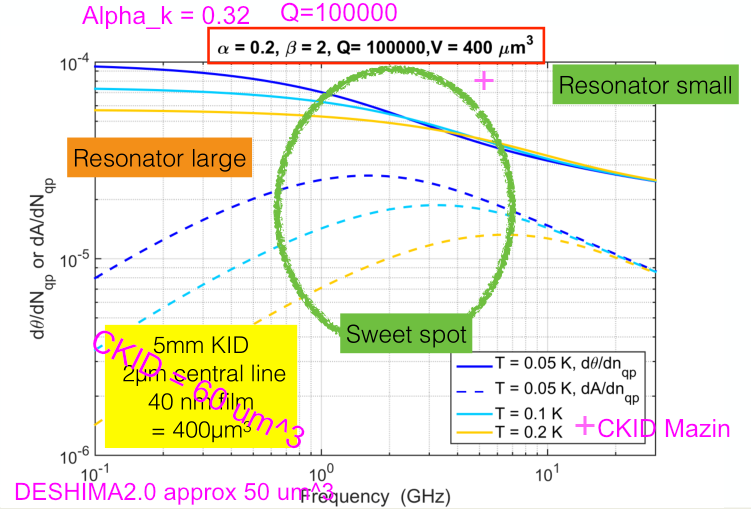

(Source: Slides Superconduting astronomical instumentation )

And Jochem code:


$$\frac{dA}{dN_{qp}} = -2.66\cdot 10^{-5}$$



$$\frac{d\theta}{dN_{qp} }= 7.23\cdot 10^{-5}$$


% Start-----Compare Mazin 
CKID.Qi = 2E6;
CKID.Qc = 100000;
CKID.Q = (CKID.Qi*CKID.Qc)/(CKID.Qi + CKID.Qc);
Alu.length = 1000; %[um] (Me: Also in m in Jochem code)
Alu.width = 2; %[um] (Me)
Alu.height = 0.030; %[um](Me)
Alu.V = Alu.length*Alu.width*Alu.height ; %[um^3] (Me)(Checked)
CKID.phaseresponsivity = dphaseMazin(0.32,CKID.Q,Alu.V)


disp('dthetadNqp Mazin = '+string(CKID.phaseresponsivity));
% End ------Compare Mazin


### End intermezzo

## Stitching Jochem code: Obtaining resposivity

Temp = [ 0.2 0.1 0.05];
for j=1:length(Temp)
%Parameters necessary for getNqp_Tbath function.
Alu.Teff = 0.05; % [K] (Source: Jochem code)(Checked) 
Alu.Tc          = 1.125;    % [K] (Source: Jochem code)(Checked)
Alu.eta_pb      = 0.4;      % (Source: Jochem code)(Checked)pair breaking eficiency 0.4 for medium thin aluminium on Si, 0.56 for thick Alu
Alu.tau0        = 4.38e-7;   % (Source: Jochem code)(Checked)Kaplan single particle tau_0. 438e-9 is the Kaplan value. Can change and our old papers have a factor wrong here
KID.Tbath = 0.05 ; % [K] (Source: Jochem code)

%---> Begin global constants from Jochem code:
global hbar kb e_c c mu0 eps0 N0 vf ksi0 lambda0 tau0;%in SI units
% constants
e_c=1.602e-19;          %single electron charge in C
kb=1.3806503e-23;       %boltzmann contstant J/K
hbar=6.60607e-34/2/pi;  %1.054571e-34;  %reduced plancks constant
mu0=4*pi*1e-7;          %Permeability of vacuum
eps0=8.8541878e-12;       %delectric consant of vacuum 
c=2.99792e8;               %speed of light
tau0=458e-9;                %in sec. from PRL PdV
%%%%%%%%%%%% fixed parameters alumninium %%%%%%%%%%%%
N0 = 1.72e10/e_c;             %density of states in /J/um^3
vf = 2.03e6;                  %Fermi Velocity m
ksi0 = 1.6e-6;        %coherence length bulk m
lambda0 = 16e-9;      %penetration depth bulk m
%---> End global constants Jochem code.




sigma_n_Al = 3.77E7; % [Siemens/m] Source: https://en.wikipedia.org/wiki/Electrical_resistivity_and_conductivity

[Alu.nqp, Alu.tauqp, Alu.Nqp, KID.NEPGR] = getNqp_Tbath(Alu.Tc, Alu.eta_pb, Alu.V, KID.Tbath, Alu.tau0);% Jochem


Alu.l_elec = 5.838E-9; % (Source Jochem code) Jochem says beta is electron mean free path. Strange but ok!
KID.alphatot = alpha_c_alu_Origin2500;%(Me)
KID.Qc = 100000;%(Me)
Alu.t = 30e-9; %(Me)
Qim = 2000000;%(Me, For now this is a guess)
Alu.N0   =1.0737E29  ;% (Source: Jochem code)
Alu.Delta= 0.1706 ;% (Source: Jochem code )
Alu.Teff =0.150; % [K](Source: Jochem code)
KID.Fres = linspace(1E9,9E9,100);%(Me)
for i=1:length(KID.Fres)
%beta = calcbeta(KID.Fres(i),epsilon_eff,phyconst.c);
[Alu.sigma1,Alu.sigma2,Alu.ds1dn,Alu.ds2dn]= Sigmas(2*pi*KID.Fres(i), Alu.N0, Alu.Delta, Alu.Teff);      %MB equations, vaklkid for T<<Tc, F<<Fgap
[KID.dthetadN,KID.dAdN,KID.dxdN,Alu.abssigma,KID.Qi,KID.Q,Alu.Beta]= getresponsivity2(Alu.l_elec,KID.alphatot,KID.Qc,Alu.V,Alu.sigma1,Alu.sigma2,Alu.ds1dn,Alu.ds2dn,Alu.t,Qim);
Jout_dthetadN(i,j) = (Alu.V./(KID.alphatot.*KID.Qc)).*KID.dthetadN;
Jout_dAdN(i,j) = (Alu.V./(KID.alphatot.*KID.Qc)).*KID.dAdN;
end 
end                    
% Plotting of this obtained data:
 
f3 = figure
ax = axes('XScale', 'linear', 'YScale', 'log');
hold on
for j=1:1
plot(KID.Fres,Jout_dthetadN(:,j),'linewidth',2)
plot(KID.Fres,abs(Jout_dAdN(:,j)),'linewidth',2)%Caution: took the absolute value to make it work on log scale
end
hold off
title('Responsivity coof as function of frequency')
xlabel('freq [Hz]')
ylabel('$|R_{-}|$','Interpreter','latex' )
legend('\theta','A')
% '\frac{}{dN_{qp}}'
grid minor
set(gca,'linewidth',1)


                                                  %[dthetadN,dRdN,dxdN,abssigma,Qi,Q,Beta] = getresponsivity2(length,alphak,Qc,V,sigma1,sigma2,ds1dn,ds2dn,d,Qim)
%Display the found responsivity and sigmas
disp('dthetadN = '+string(KID.dthetadN)+'\n');
disp('dAdN = '+string(KID.dAdN)+'\n');

## Noise: PSD plots papers

The goal of this section is to visualize the PSD of the different noise sources found in the following papers:

### Paper 5: 

Here is a slider for 


$$P={10}^x$$


typical values range from 

fW: x=

p5_x= -14.4;
p5_P_sky = 10^p5_x;
p5_freq_sky = linspace(220E9,440E9,1000);
p5_NEP_photon = zeros(1,length(p5_freq_sky));
p5_NEP_gr = zeros(1,length(p5_freq_sky));

In slides SAI:


$$\Delta = 1.76 k_{B}T_c$$


And in (Thoen, 2016, Superconducting NbTiN Thin Films... )

Tc,NbTiN = 15K - 15.3K

Tc,Al = 1.28K

p5_TcNbTiN = 15.15;
p5_TcAl = 1.28
p5_Delta = (1.76*phyconst.kb*p5_TcAl);
p5_etapb = 0.6;
for i=1:length(p5_freq_sky)
p5_NEP_photon(i) = sqrt(2*p5_P_sky*phyconst.h*p5_freq_sky(i));
p5_NEP_gr(i)  = sqrt((2*p5_P_sky*p5_Delta)/p5_etapb);
end
f4 = figure
ax2 = axes('XScale', 'log', 'YScale', 'log');
hold on 
plot(p5_freq_sky,p5_NEP_photon)
plot(p5_freq_sky,p5_NEP_gr)

xlabel('freq [Hz]')
ylabel('NEP_{photon.approx}')
grid minor
hold off

# Appendix

Additional programs that can come in handy(You don't need to run these.)

## Graphs Paper 5:Photon-noise limited radiation detection

## **Transmission-line Matrix multiplier(TlMM)**

Second attempt at creating code that does transmission line calculations. Now I am taking the approach by Alejandro.

### **Dependencies:**

This is a list of the known depedencies:

RF Toolbox functions(abcd2z,...

calcbeta.m

PPCAreatocap.m

and everything in the folder:

/Functions_TLMM

### Setup:

And adding path to the functions that we use. This mainly contains functions to convert S parameters

addpath('.\Functions_TLMM')

### User input:

Here I decide what the freq range is that I want to simulate. 


tlmm_freq_begin = 1E9;    % [Hz]
tlmm_freq_end   = 9E9;    % [Hz]
tlmm_freq_N     = 100000;
%for i = 1:length(tlmm_freq)
%testz =  -50 + 1E8.*tlmm_freq
%end % Custom Zin to test


tlmm_Z0ref      = 50;
tlmm_Zload      = 0;      % [Ohm]

tlmm_CPWprop.eps_eff= 10.6009;% [-]
tlmm_CPWprop.Z0     = 76.28;  % [Ohm]
tlmm_CPWprop.length = 0.001;  % [m]

tlmm_PPCprop.Width  = 50E-6;  % [m]
tlmm_PPCprop.Height = 50E-6;  % [m]
tlmm_PPCprop.thickness= 250E-9% [m]
tlmm_PPCprop.Area   = tlmm_PPCprop.Width*tlmm_PPCprop.Height;
tlmm_PPCprop.epsr   = 10   ;  % [-]
tlmm_PPCprop.C      = PPCAreatocap(tlmm_PPCprop.Area,tlmm_PPCprop.thickness,tlmm_PPCprop.epsr,'base') % [F]

tlmm_MSLprop.eps_eff= 61.047;% [-]
tlmm_MSLprop.Z0     = 17.578;  % [Ohm]
tlmm_MSLprop.length = 20E-6;  % [m]

tlmm_Couplerprop.Width  = 4E-6;  % [m]
tlmm_Couplerprop.Height = 8E-6;  % [m]
tlmm_Couplerprop.thickness= 250E-9;% [m]
tlmm_Couplerprop.Area   = tlmm_Couplerprop.Width*tlmm_Couplerprop.Height;
tlmm_Couplerprop.epsr   = 10   ;  % [-]
tlmm_Couplerprop.C      = PPCAreatocap(tlmm_Couplerprop.Area,tlmm_Couplerprop.thickness,tlmm_Couplerprop.epsr,'base') % [F]

tlmm_Throughlineprop.eps_eff= 7.9096;% [-]
tlmm_Throughlineprop.Z0     = 49.0504;  % [Ohm]
tlmm_Throughlineprop.length = 1; % [m] %Warning: This is kinda random at this moment

### Allocation:

tlmm_CPW      =   zeros(2,2,tlmm_freq_N);
tlmm_PPC      =   zeros(2,2,tlmm_freq_N);
tlmm_MSL      =   zeros(2,2,tlmm_freq_N);
tlmm_Coupler  =   zeros(2,2,tlmm_freq_N);
tlmm_Sys      =   zeros(2,2,tlmm_freq_N);
tlmm_Zsys     =   zeros(2,2,tlmm_freq_N);
tlmm_Throughlinep =zeros(2,2,tlmm_freq_N);
tlmm_Sparameters =  zeros(2,2,tlmm_freq_N);
tlmm_Shunt    = zeros(2,2,tlmm_freq_N); 
tlmm_InThroughline = zeros(2,2,tlmm_freq_N); 
tlmm_Zin      = zeros(1,tlmm_freq_N);
tlmm_S21      = zeros(1,tlmm_freq_N);

### Calculations to get system matrices:

tlmm_freq = linspace(tlmm_freq_begin,tlmm_freq_end,tlmm_freq_N);
for i = 1:length(tlmm_freq)
tlmm_CPW(:,:,i) =     tlmm_TL_ABCD(tlmm_freq(i),tlmm_CPWprop);
tlmm_PPC(:,:,i) =     tlmm_ParCAP_ABCD(tlmm_freq(i),tlmm_PPCprop);
tlmm_MSL(:,:,i) =     tlmm_TL_ABCD(tlmm_freq(i),tlmm_MSLprop);
tlmm_Coupler(:,:,i) = tlmm_SeriesCAP_ABCD(tlmm_freq(i),tlmm_Couplerprop);

%tlmm_Sys(:,:,i) = tlmm_Coupler(:,:,i)*tlmm_MSL(:,:,i)*tlmm_PPC(:,:,i)*tlmm_CPW(:,:,i);
tlmm_Sys(:,:,i) = tlmm_Coupler(:,:,i)*tlmm_CPW(:,:,i);
tlmm_Throughline(:,:,i) = tlmm_TL_ABCD(tlmm_freq(i),tlmm_Throughlineprop);
end % End of for loop for calculating matrices

### Convert to Impedance Matrices:


tlmm_Zsys(:,:,i)   = abcd2z(tlmm_Sys(:,:,i));

### Calculate input impedance of CKID as seen from coupler:

for i = 1:length(tlmm_freq)
tlmm_Zin(i)   = tlmm_ZmatrixtoZin(tlmm_Sys(:,:,i),tlmm_Zload);
end % End of for loop for calculating matrices

### Place shunt inside of Through-line:

for i = 1:length(tlmm_freq) 
%tlmm_Shunt(:,:,i)        = tlmm_Shunt_ABCD(tlmm_Zin(i));%Caution
tlmm_Shunt(:,:,i)        = tlmm_Shunt_ABCD(tlmm_Zin(i));%Caution
tlmm_InThroughline(:,:,i) = tlmm_Shunt(:,:,i);%Caution!! Removed the thoughline
end 

### Calculate S_21:

tlmm_Sparameters  = abcd2s(tlmm_InThroughline,tlmm_Z0ref);
for i = 1:length(tlmm_freq) 
tlmm_S21(i) = tlmm_InThroughline(2,1,i);
end 

### Plot!


subplot(1,2,1)
plot(tlmm_freq,10*log10(abs(tlmm_S21)));
subplot(1,2,2)
plot(tlmm_freq,tlmm_Zin)

**Zin**

**|S21| **

## Optional: Symbolic Matrix Multiplier(SMM) 

*Warning: it is quite slow!! can take like a few minutes to run.*

This is an additional program that can calculate the ABCD matrices for the CKID. There is however an error in there because the obtained S21 parameters don't start at 0dB which makes no sense.

Do you want to run this section? *Check the checkbox* 

RunSMM = false
if RunSMM

syms theta
syms Z
syms Z0
syms freq
syms C_PPC
syms C_c

COUPLER = [1 -1j*(1/(2*pi*freq*C_c));0 1];
PPC = [1   0 ; 1j*2*pi*freq*C_PPC 1];
CPW = [cos(theta) 1j*Z0*sin(theta) ; 1j*(1/Z0)*sin(theta) cos(theta) ];
SHORT = [1 0;1/Z  1 ];

SHORTED_CPW = CPW*SHORT;
ZIN_SHORTED_CPW = SHORTED_CPW(1,1)/SHORTED_CPW(2,1);
LIM_SHORTED_CPW = limit(ZIN_SHORTED_CPW,Z,0);
RES = PPC*CPW*SHORT ;
TOT = COUPLER*PPC*CPW*SHORT;
ZIN_RES = RES(1,1)/RES(2,1);
LIM_RES = limit(ZIN_RES,Z,0);
ZIN_TOT = TOT(1,1)/TOT(2,1);
LIM_TOT = limit(ZIN_TOT,Z,0);
disp(LIM_TOT);

%Parameters:
Z0 = 76.28;
C_PPC = 0.918E-12;%C_PPC = 2E-12;%C_PPC = 0.918E-12;% Capacitance value for the PPC.
C_c = 5.66E-15; %Capacitance value for the coupler.
l = 0.001;
c = 2.98E8;
epsilon_eff = 10.6009;
theta = 2*pi*((sqrt(epsilon_eff)*freq)/c)*l;

subput_RES = subs(LIM_RES);
subput_TOT = subs(LIM_TOT);
freq = linspace(5.5E9,5.6E9,10000);
Output_RES = subs(subput_RES);
Output_TOT = subs(subput_TOT);
figure
hold on

plot(freq,imag(double(Output_RES)));
plot(freq,imag(double(Output_TOT)));
grid on
%xlim([5E9 6E9])
ylim([-10000 10000])
title('Input impedance calculated with ABCD formalism');
legend('PPC + CPW + Short','coupler + PPC + CPW + Short')
xlabel('freq [Hz]')
ylabel('Im(Z_{11}) [\Omega])')
hold off


%% Including the beginning and the end of the readout line 

syms Z_s
syms Z0_rl
syms Z_ref
syms theta_rl % for now we assume symmetry.
ZKID = [1 0;1/Z_s 1];%Compact kid modeled as shunt impedance
TL = [cos(theta_rl) 1j*Z0_rl*sin(theta_rl) ; 1j*(1/Z0_rl)*sin(theta_rl) cos(theta_rl) ];
SYSTEM = TL*ZKID*TL;
%Now we want to put in the info we obtained about Z_in_kid
double_output_tot = double(Output_TOT);
Z0_rl = 50;
Z_ref = 50;
theta_rl = 2*pi*((sqrt(epsilon_eff)*freq)/c)*l;
%clear freq
%syms freq
theta = 2*pi*((sqrt(epsilon_eff)*freq)/c)*l;
Z_s = LIM_TOT;
%freq = linspace(1E9,9E9,800);

SOUT = subs(SYSTEM);
S21_sym = 2/(SOUT(1,1) +(SOUT(1,2)/Z_ref)+ SOUT(2,1)*Z_ref + SOUT(2,2));% I want this to be a function of freq only.
%% Plotting
figure
subplot(2,1,1)
plot(freq,20*log10(abs(double(subs(S21_sym)))))
xlabel('freq [Hz]')
ylabel('|S_{21}| [dB]')
title('Analytic calculation of S_{21}');
legend('Mag','phase');
subplot(2,1,2)
plot(freq,angle(double(subs(S21_sym))),'--');
xlabel('freq [Hz]')
ylabel('arg(S_{21}) [rad]')
else
disp('RunSMM = false So not running this part')
end

## **Matrix multiplier**